# 自动场景生成

此示例说明如何使用 `drivingScenario `对象自动生成场景。在此示例中，您将自动化：

- 通过定义车辆的起始位置和目标位置来放置场景中的车辆

- 车辆从起始位置到目标位置的路点选择和轨迹生成。

- 调整速度，使车辆加速或减速，以避免在同一车道上行驶的其他车辆发生碰撞。

您可以使用此示例合成多个随机场景来测试驾驶算法。

**介绍**

Automated Driving Toolbox™ 中的对象和 Driving Scenario Designer 应用程序是生成合成驾驶场景的有效 [`drivingScenario`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.html) 工具[。](https://ww2.mathworks.cn/help/driving/ref/drivingscenariodesigner-app.html)您可以创建道路网络或从 OpenDRIVE®、HERE 高清实时地图和 OpenStreetMap® 导入道路网络。然后，您可以将演员或车辆添加到道路网络并定义他们的轨迹以合成驾驶场景。生成轨迹所需的路点必须仔细选择，以使车辆的轨迹位于道路网络内，并且车辆在沿着轨迹行驶时不会发生碰撞。定义此类车辆放置和轨迹通常需要多次试验，如果您有大型道路网络和许多车辆需要配置，则非常耗时。

此示例提供了帮助函数，并演示了使用该对象自动执行车辆放置和轨迹生成的步骤 [`drivingScenario`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.html)。您还可以将生成的场景导出到 [Driving Scenario Designer](https://ww2.mathworks.cn/help/driving/ref/drivingscenariodesigner-app.html)应用程序。该示例的其余部分演示了自动化场景生成中涉及的这些步骤。

- **导入道路网络**- 使用辅助函数将 OpenStreetMap® 道路网络导入到驾驶场景对象中`helperOSMimport`。

- **定义起点和目标位置**- 指定道路网络中的感兴趣区域 (ROI)，以使用辅助函数选择车辆的起点和目标位置`helperSamplePositions`。

- **生成车辆轨迹**- 使用辅助函数`helperGenerateWaypoints`和[`trajectory`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.trajectory.html)函数生成航路点和轨迹`.`

- **修改速度配置文件以避免碰撞**- 使用 Simulink® 模型修改场景中车辆的速度配置文件`CollisionFreeSpeedManipulator`。该模型检查每辆车的速度曲线，并防止它们在沿着轨迹行驶时相互碰撞。该模型的输出是一个没有车辆碰撞的更新场景。`CollisionFreeSpeedManipulator`您可以使用辅助函数将 Simulink 模型的输出转换为驾驶场景对象`helpergetCFSMScenario`。

- **模拟和可视化生成的场景**- 使用该[`plot`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.plot.html)功能模拟和显示自动生成的场景。[您还可以使用Driving Scenario Designer](https://ww2.mathworks.cn/help/driving/ref/drivingscenariodesigner-app.html)应用程序阅读和模拟场景。

**导入路网**

[您可以从https://www.openstreetmap.org](https://www.openstreetmap.org/)下载道路网络，它提供对全世界众包地图数据的访问。数据根据开放数据共享开放数据库许可证 (ODbL) 获得许可，[https://opendatacommons.org/licenses/odbl/](https://opendatacommons.org/licenses/odbl/)。

[`openstreetmap.org`](https://www.openstreetmap.org/)使用函数指定要从中导入 MCity 测试设施地图的边界框坐标`helperOSMImport`。该函数返回一个驾驶场景对象，其中包含来自导入的地图数据的道路网络。您还可以使用该[`roadNetwork`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.roadnetwork.html)功能从 OpenDRIVE®、HERE 高清实时地图或 OpenStreetMap® 文件导入道路网络。

% Import the road network of MCity
minLat =  42.2990;
maxLat =  42.3027;
minLon = -83.6996;
maxLon = -83.6965;
bbox = [minLat maxLat;minLon maxLon];
scenario = helperOSMImport(bbox); % 需要安装variantgenerator.mlpkginstall，否则出现无法解析名称 'variantgenerator.internal.getRoadInfoFromScenario'
% Create another scenario object for plotting purposes
scenario_in = helperOSMImport(bbox);

使用该`plot`函数显示 MCity 道路网络。

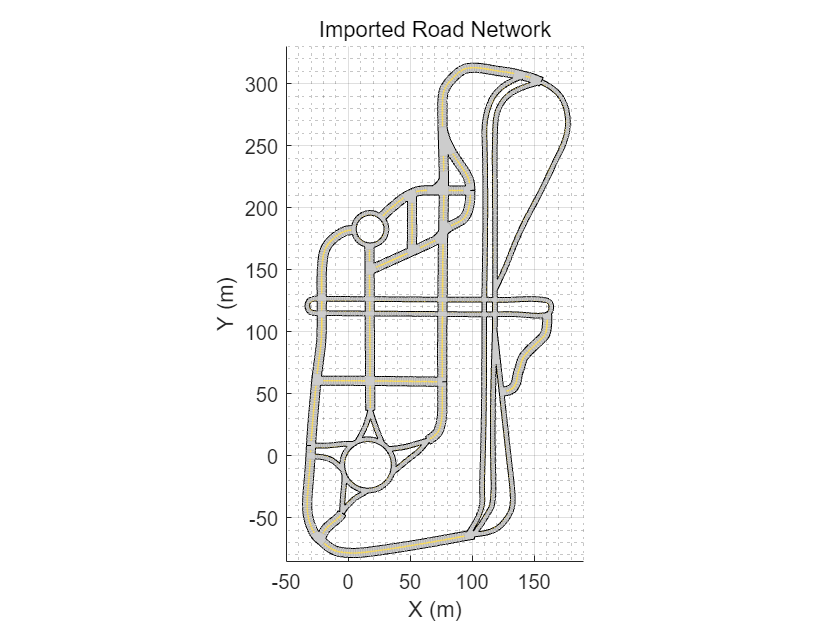

figure
plot(scenario_in)
title("Imported Road Network")
xlim([-50 190])
ylim([-85 330])

## **定义开始和目标位置**

要创建驾驶场景，您必须首先在道路网络上定义特定点，这些点可以作为场景中车辆的起点和终点位置。使用该`helperSamplePositions`函数在道路网络中生成一组随机的这些点。您可以使用一个或多个函数的名称-值对参数`helperSamplePositions`以不同方式配置起始位置和目标位置”

- 使用“ `Seed`”指定用于生成随机点的随机生成器设置。您可以选择生成的集合中的任何点作为开始和目标位置。

- 使用“ `ROI`”在要定义起点和目标位置的道路网络中指定一个或多个 ROI。ROI 可以是圆形、矩形或具有任意数量顶点的多边形区域。ROI 的值是一个*N* × 2 矩阵，指定封闭区域的空间坐标。如果未指定此值，则该函数会在整个道路网络中生成随机点。

- 使用“ `Lanes`”指定要在其中定义起始位置和目标位置的车道。要选择单个车道，请将车道编号指定为标量值。对于多车道，“ ”的值`Lanes`必须是包含所需车��道编号的向量。如果未指定此值，该函数将随机选择车道。

- 使用 ' `LongitudinalDistance`' 设置两个连续点之间的纵向距离。如果未指定此值，则该函数会在同一车道上的两个连续点之间施加至少 5 米的距离。这意味着放置在同一车道上的两辆连续车辆之间的纵向距离至少为 5 米。

在模拟过程中，车辆在起点生成，然后行驶至目标点。

### **1.选择起始位置**

生成 10 个随机点用作潜在的起始位置。指定用于设置随机数生成器的标志。将 的值设置`setSeed`为 1 以指定随机数生成器的种子。`helperSamplePositions`使用“ `Seed`”名称-值对组参数将随机生成器设置作为输入传递给函数。

该`helperSamplePositions`函数输出导入道路网络中随机选择点的 3-D 空间坐标。该函数还输出相对于所选点的偏航角。相对于一个点获得的偏航角定义了车辆放置在该点的方向。

numPoints = 10;
setSeed = 2;
rng(setSeed);
s = rng;
[points,yaw] = helperSamplePositions(scenario,numPoints,"Seed",s);

指定场景中要放置的车辆数量为3。在生成的集合中选择任意三个点作为车辆的起始位置。

numVehicles = 3;
startSet1 = [points(2,:);points(4,:);points(7,:)];
yaw1 = [yaw(2);yaw(4);yaw(7)];
mesh = driving.scenario.carMesh;

使用该[`vehicle`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.vehicle.html)功能将车辆放置在选定的点。

for idx = 1 : numVehicles
    vehicle(scenario,Position=startSet1(idx,:),Yaw=yaw1(idx),ClassID=1,Mesh=mesh);
end

通过定义 ROI 生成另一组点。计算坐标以指定圆形 ROI。

xCor = 0;
yCor = 0;
radius = 50;
theta = 0: pi/10: 2*pi;
roiCircular(:,1) = xCor+radius*cos(theta);
roiCircular(:,2) = yCor+radius*sin(theta);

指定要在 ROI 内生成的点数和要在 ROI 内放置的车辆数为 3。选择圆形 ROI 内的所有点作为车辆的起始位置。

numPoints = 3;
% [startSet2,yaw2] = helperSamplePositions(scenario,numPoints, ROI=roiCircular);
% 错误使用 drivingScenario/record
% No trajectory found.  To record a scenario, you must define the trajectory of at least one actor.
% 暂时使用matlab 2023a运行的结果代替
startSet2 = [-23.3723    8.0685   -0.0001
  -27.3458   20.5612   -0.0000
  -29.0475   -7.8170   -0.0005];
yaw2 = [179.2031
   85.8081
   86.0247];

for idx = 1 : size(startSet2,1)
    vehicle(scenario,Position=startSet2(idx,:),Yaw=yaw2(idx),ClassID=1,Mesh=mesh);
end

指定矩形 ROI 的坐标。将要在 ROI 内生成的点数和要放置在 ROI 内的车辆数设置为 3。将同一车道中两个连续点之间的纵向距离设置为 30 米。如果 ROI 不足以容纳指定纵向距离处的指定点数，则该`helperSamplePositions`函数仅返回 ROI 内可以容纳的点数。要获得所需的点数，您必须减少纵向距离或增加 ROI 的面积。

roiRectangular = [0 0;100 100];
numPoints = 3;
% [startSet3,yaw3] = helperSamplePositions(scenario,numPoints,ROI=roiRectangular,LongitudinalDistance=30);
startSet3 = [26.3934   62.0416    0.0010
   73.9895   42.7174    0.0009
   73.9965   64.4358    0.0011];
yaw3 = [179.2899
  -90.2432
  -89.5015];


使用该[`vehicle`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.vehicle.html)功能将车辆放置在选定的点。

for idx = 1 : size(startSet3,1)
    vehicle(scenario,Position=startSet3(idx,:),Yaw=yaw3(idx),ClassID=1,Mesh=mesh);
end

绘制生成的样本点和 ROI。

figScene = figure(Name="AutomaticScenarioGeneration");
set(figScene,Position=[0,0,900,500]);

hPanel1 = uipanel(figScene,Position=[0 0 0.5 1]);
hPlot1 = axes(hPanel1);
plot(scenario_in,Parent=hPlot1,Meshes="on");
title("Points for Selecting Start Positions")
hold on
plot(points(:,1),points(:,2),"ro",MarkerSize=5,MarkerFaceColor="r");

plot(roiCircular(:,1),roiCircular(:,2),LineWidth=1.2,Color="k");
plot(startSet2(:,1),startSet2(:,2),"ko",MarkerSize=5,MarkerFaceColor="k");

plot([roiRectangular(1,1);roiRectangular(1,1);roiRectangular(2,1);roiRectangular(2,1);roiRectangular(1,1)], ...
     [roiRectangular(1,2);roiRectangular(2,2);roiRectangular(2,2);roiRectangular(1,2);roiRectangular(1,2)], ...
     LineWidth=1.2,Color="b");
plot(startSet3(:,1),startSet3(:,2),"bo",MarkerSize=5,MarkerFaceColor="b");
xlim([-50 190])
ylim([-85 330])
hold off

显示场景中的起始位置和车辆。

- 红色的 3 个起始位置是从场景中定义的 10 个随机点中选择的。

- 黑色的 3 个起始位置是从圆形 ROI 中定义的 3 个随机点中选择的。

- 蓝色的 3 个起始位置是从矩形 ROI 中定义的 3 个随机点中选择的。

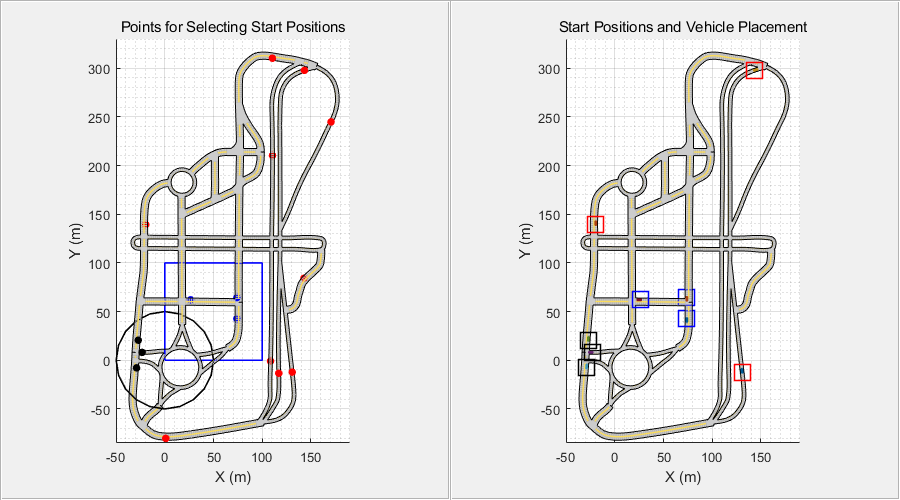

hPanel2 = uipanel(figScene,Position=[0.5 0 0.5 1]);
hPlot2 = axes(hPanel2);
plot(scenario,Parent=hPlot2,Meshes="on");
title("Start Positions and Vehicle Placement")
hold on
plot(startSet1(:,1),startSet1(:,2),"rs",MarkerSize=15,LineWidth=1.2);
plot(startSet2(:,1),startSet2(:,2),"ks",MarkerSize=15,LineWidth=1.2);
plot(startSet3(:,1),startSet3(:,2),"bs",MarkerSize=15,LineWidth=1.2);
xlim([-50 190])
ylim([-85 330])
hold off

将所有起始位置合并到一个矩阵中。起始位置的数量意味着驾驶场景中的车辆总数。

startPositions = [startSet1;startSet2;startSet3];

### **2.检查场景对象**

显示场景对象并检查其属性。`Actors`该对象的属性是`scenario`一个 1×9 数组，用于存储有关添加到驾驶场景的 9 辆车的信息。使用点索引访问属性中每辆车的详细信息`Actors`。显示驾驶场景中第一辆车的详细信息。该`Position`属性包含车辆的起始位置。

scenario

scenario =   drivingScenario - 属性:

        SampleTime: 0.0100
          StopTime: Inf
    SimulationTime: 0
         IsRunning: 1
            Actors: [1×9 driving.scenario.Vehicle]
          Barriers: [0×0 driving.scenario.Barrier]
       ParkingLots: [0×0 driving.scenario.ParkingLot]


scenario.Actors(1)

ans =   Vehicle - 属性:

         FrontOverhang: 0.9000
          RearOverhang: 1
             Wheelbase: 2.8000
             EntryTime: 0
              ExitTime: Inf
               ActorID: 1
               ClassID: 1
                  Name: ""
             PlotColor: [0 0.4470 0.7410]
              Position: [130.7903 -12.2335 -2.0759e-04]
              Velocity: [0 0 0]
                   Yaw: 96.6114
                 Pitch: 0
                  Roll: 0
       AngularVelocity: [0 0 0]
                Length: 4.7000
                 Width: 1.8000
                Height: 1.4000
                  Mesh: [1×1 extendedObjectMesh]
            RCSPattern: [2×2 double]
      RCSAzimuthAngles: [-180 180]
    RCSElevationAngles: [-90 90]


### **3.选择目标位置**

使用函数生成场景中车辆的目标位置`helperSamplePositions`。目标位置的总数必须与起始位置的总数相同。

numGoalPositions = length(startPositions)

numGoalPositions = 9

指定多边形 ROI 的坐标，并在多边形 ROI 内找到 5 个随机点。选择这些点作为场景中前 5 辆车的目标位置。

roiPolygon = [-50  170;30  250;72 170;-50 170];
numPoints1 = 5;
% goalSet1 = helperSamplePositions(scenario,numPoints1,ROI=roiPolygon);
goalSet1 = [49.5437  173.5149    0.0010
   53.1897  198.7437    0.0007
   -0.0194  179.7588    0.0006
   35.7695  198.2211    0.0006
    6.0029  188.7362    0.0006];


生成剩余的一组目标位置，使它们都位于特定的车道上。使用“ `Lanes`”名称-值对组参数指定目标位置的车道编号。

numPoints2 = 4;
% goalSet2 = helperSamplePositions(scenario,numPoints2,Lanes=1);
goalSet2 = [108.1520  -34.7885   -0.0005
  118.4150  192.4992    0.0005
  110.0865  248.1703   -0.0003
  177.2049  267.6814   -0.0016];

显示场景和选定的目标位置。

- 红色的 5 个点显示多边形 ROI 中定义的目标位置。

- 蓝色的 4 个点显示了在整个场景中定义的目标位置。

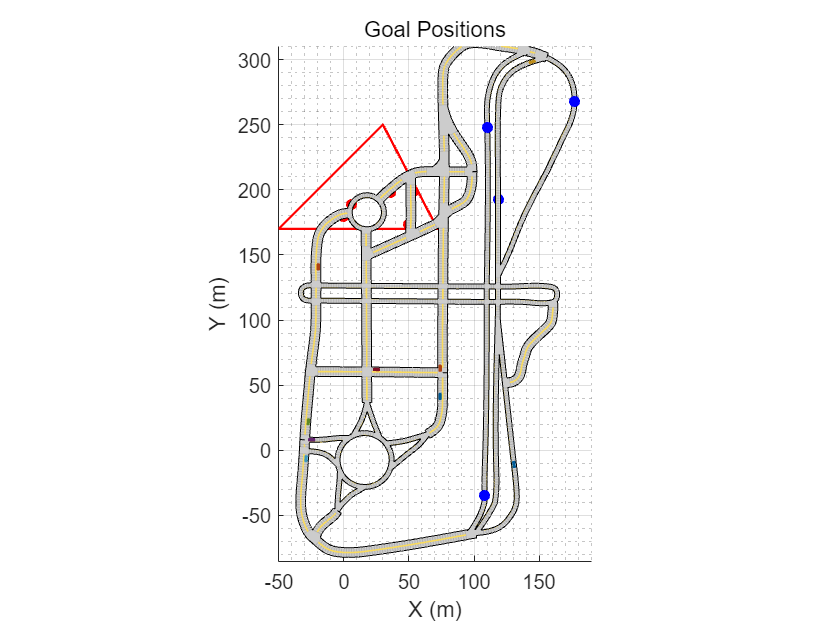

figure
plot(scenario,Meshes="on"); 
title("Goal Positions")
hold on
plot(roiPolygon(:,1), roiPolygon(:,2), LineWidth=1.2, Color="r")
plot(goalSet1(:,1), goalSet1(:,2), "ro", MarkerSize=5, MarkerFaceColor="r")
plot(goalSet2(:,1), goalSet2(:,2), "bo", MarkerSize=5, MarkerFaceColor="b")
xlim([-50 190])
ylim([-85 310])
hold off

将所有目标位置合并到一个矩阵中。

goalPositions = [goalSet1;goalSet2];

显示场景中每辆车的起始位置和目标位置。

vehicleNum = 1:length(startPositions);
table(vehicleNum(:),startPositions,goalPositions,VariableNames={'Vehicle','Start positions','Goal positions'})

ans = 9×3 table
    Vehicle               Start positions                      Goal positions        
    _______    _____________________________________    _____________________________

       1        130.79        -12.233    -0.00020759     49.544     173.51      0.001
       2       -19.606         139.45     0.00065289      53.19     198.74     0.0007
       3        143.37          297.8       -0.00188    -0.0194     179.76     0.0006
       4       -23.372         8.0685        -0.0001      35.77     198.22     0.0006
       5       -27.346         20.561              0     6.0029     188.74     0.0006
       6       -29.047         -7.817        -0.0005     108.15    -34.788    -0.0005
       7        26.393         62.042          0.001     118.42      192.5     0.0005
       8         73.99         42.717         0.0009     110.09     248.17    -0.0003
       9        73.996         64.436         0.0011      177.2     267.68    -0.0016


## **生成车辆轨迹**

使用该`helperGenerateWaypoints`函数计算连接起始位置和目标位置的路点。该函数返回一个结构数组，其中包含场景中每辆车的道路中心、计算的路点和偏航角。从对象中读取车辆信息`scenario`并为每辆车指定随机速度值。使用该[`trajectory`](https://ww2.mathworks.cn/help/driving/ref/drivingscenario.trajectory.html)函数通过使用计算出的路点和随机速度值为每辆车生成轨迹。

info = helperGenerateWaypoints(scenario,startPositions,goalPositions);
for indx = 1:length(startPositions)
    vehicleData = scenario.Actors(indx);
    speed = randi([10,25],1,1);
    waypts = info(indx).waypoints;
    trajectory(vehicleData,waypts,speed);
end

设置场景的停止时间。

scenario.StopTime = 50;

创建自定义图形并显示模拟驾驶场景。

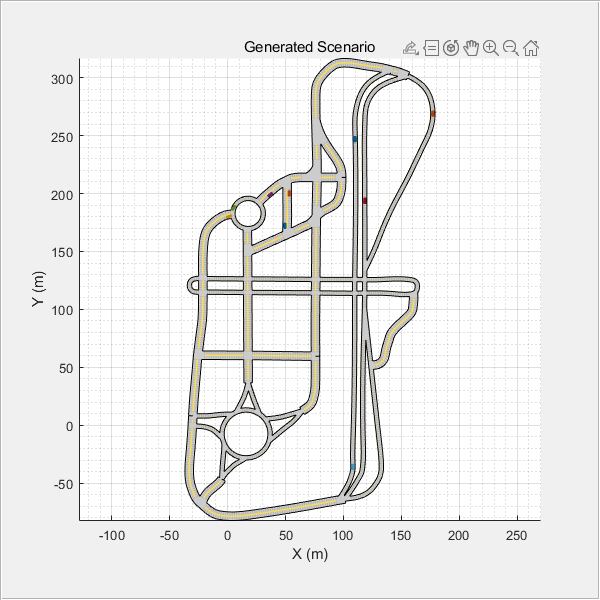

close all;
figScene = figure;
set(figScene,Position=[0,0,600,600]);
movegui(figScene,"center");
hPanel = uipanel(figScene,Position=[0 0 1 1]);
hPlot = axes(hPanel);
plot(scenario,Parent=hPlot,Meshes="on");
title("Generated Scenario")
while advance(scenario)
end

在生成的场景中，所有车辆以特定速度沿着它们的轨迹移动以到达它们的目标位置。您还可以观察两个演员在沿其轨迹移动时发生的碰撞。在合成用于测试驾驶算法的场景时，重要的是场景中的车辆不会发生碰撞。为防止碰撞，您必须调整车辆的速度，使它们在沿路径行驶时不会相互碰撞。

### **修改速度曲线以避免碰撞**

使用 MATLAB® System object™`CollisionFreeTrajectory`校正车辆的速度，使它们在沿着轨迹行驶时不会发生碰撞。该模型使用非线性时间缩放来反应性地加速或减速车辆而不改变其轨迹 [1]。

collisionFreeObj = helperCollisionFreeTrajectory(Scene=scenario);
out = cell(numel(0:0.025:50),1);
scenario.SampleTime = 0.025;
index = 1;
for time = 0:0.025:50
    out{index} = collisionFreeObj(time);
    index = index+1;
end

### **模拟和可视化生成的场景**

使用该`helpergetCFSMScenario`函数将输出转换`CollisionFreeTrajectory`为驾驶场景对象。模拟并显示驾驶场景。您可以看到车辆沿着指定的轨迹行驶以到达其目标位置。

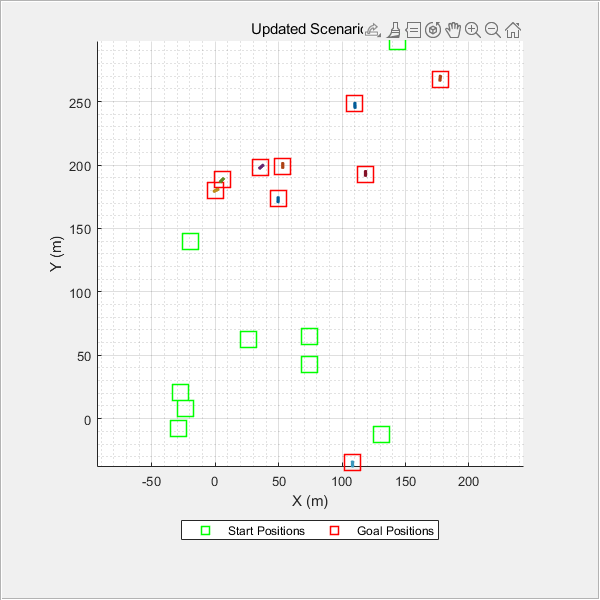

% 未识别类 'drivingScenario' 的方法、属性或字段 'Scene'。
% 出错 helperCreateCFSMScenario (第 12 行)
% ds.Scene = currScenario.Scene;
% 注释掉了currScenario.Scene 和 currScenario.RoadHistory 所在的代码行
newScenario = helperCreateCFSMScenario(out,scenario);

close all;
figScene = figure;
set(figScene,Position=[0,0,600,600]);
movegui(figScene,"center");
hPanel = uipanel(figScene,Position=[0 0 1 1]);
hPlot = axes(hPanel);
plot(newScenario,Parent=hPlot,Meshes="on");
title("Updated Scenario")
hold on
h1 = plot(goalPositions(:,1),goalPositions(:,2),"rs",MarkerSize=15,LineWidth=1.2);
h2 = plot(startPositions(:,1),startPositions(:,2),"gs",MarkerSize=15,LineWidth=1.2);
legend([h2 h1],{"Start Positions";"Goal Positions"},Location="southoutside",Orientation="horizontal")
hold off
while advance(newScenario)
end

您还可以将场景导出到[Driving Scenario Designer](https://ww2.mathworks.cn/help/driving/ref/drivingscenariodesigner-app.html)应用程序并运行模拟。

`drivingScenarioDesigner(newScenario)`

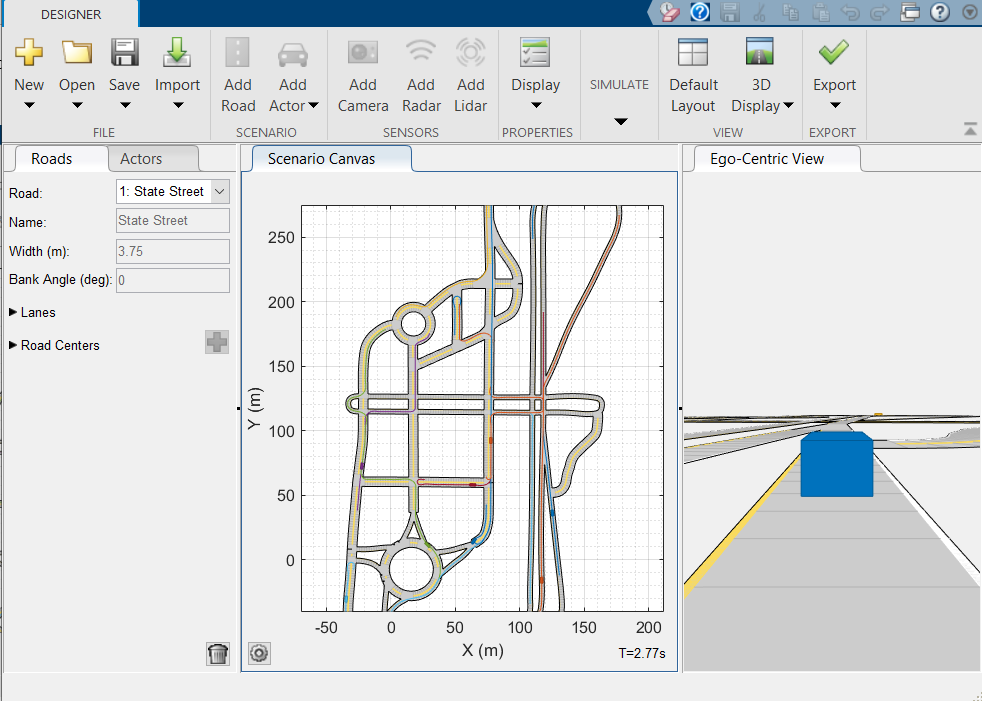

**避免碰撞的提示**

MATLAB System 对象`CollisionFreeTrajectory`仅调整活动车辆的速度曲线。一旦车辆到达目标位置并在场景中变得不活跃，就不会考虑检查碰撞。如果要生成具有非碰撞车辆的驾驶场景，请选择距离较近且位于不同车道的点作为起点和目标位置。如果有另一辆车的目标位置靠近非主动车辆并且轨迹与非主动车辆的轨迹相同，则这些车辆之间将发生碰撞。类似地，当在相同或不同车道上行驶的两辆车在道路交叉口非常接近时，就会发生碰撞。此外，如果两个或更多球门位置位于同一条车道上，则发生碰撞的可能性会更大。

- 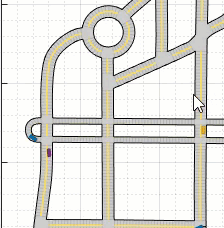               2.  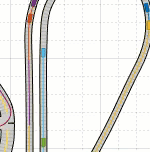

*Copyright 2020-2022 The MathWorks, Inc.*